`Homework 1 (UQ4PDE)`

Initial values

n = 50;
M = 100;

% For the plots
[x, y] = meshgrid(linspace(-5, 5, n), linspace(-5, 5, n));
xv = x(:);
yv = y(:);
points = [xv, yv].';

`Task 1`

This livescript is for Task 1.4 4. Importance Sampling using a Shift Dilation technique. We want to approximate the following integral

                        
$$I:=\frac{1}{2\pi}\int_{\mathbb{R}^2} \max(e^{x_1}+e^{x_2}-K,0)\cdot e^{\frac{-(x_1^2+x_2^2)}{2}}dx_1dx_2$$


for different values of $K$, namely $K=3$ and $K=6$. First we note that

                                    
$$I = \mathbb{E}[\max(e^{X_1}+e^{X_2}-K,0)]$$


where $X_1$ and $X_2$ are two independent standart Gaussians. First we plot the function $f(x) = \max(e^{x_1}+e^{x_2}-K,0)$ for $K\in\{3,6\}$.

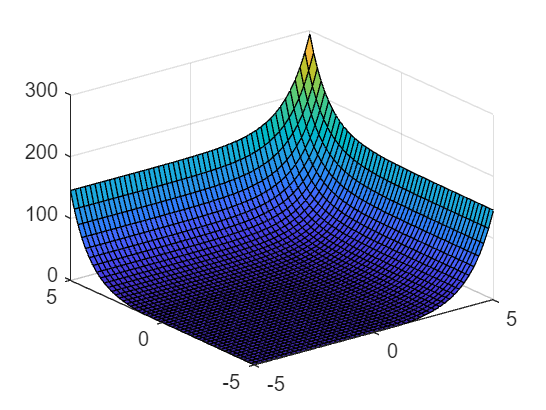

Z3 = reshape(f_max_exp_K3(points), [n n]);
Z6 = reshape(f_max_exp_K6(points), [n n]);

% 3D plot of the function
surf(x, y, Z3)

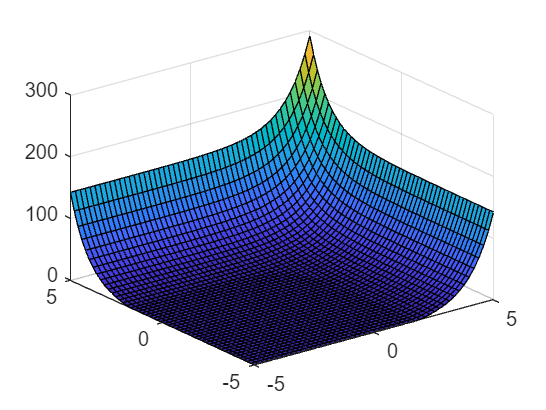

surf(x, y, Z6)

Now we estimate using Monte Carlo

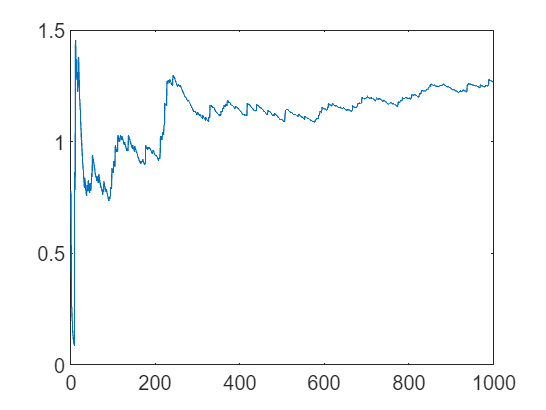

estimates_K3 = zeros([1 M]);
variances_K3 = zeros([1 M]);
estimates_K6 = zeros([1 M]);
variances_K6 = zeros([1 M]);

M = 1000;
for k=1:M
    rng(1)
    [estimates_K3(k), variances_K3(k)] = Monte_Carlo_HW1_Gaussian_Samples(@f_max_exp_K3, k);
    [estimates_K6(k), variances_K6(k)] = Monte_Carlo_HW1_Gaussian_Samples(@f_max_exp_K6, k);
end

plot(1:M, estimates_K3)

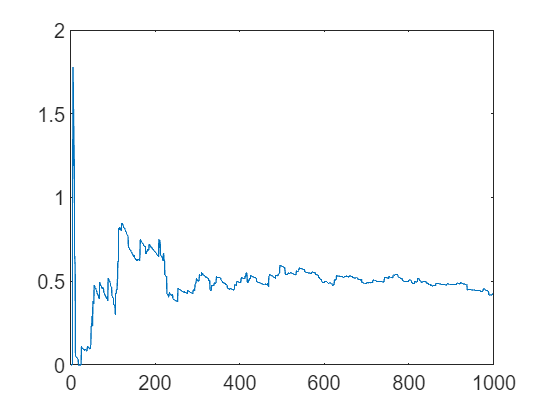

plot(1:M, estimates_K6)

Now we want to solve the problem


$$(\mu_1^\ast,\mu_2^\ast) = \text{argmax}_{x_1,x_2}\left(\max(e^{x_1}+e^{x_2}-K, 0)\cdot\rho_{x_1}(x_1)\cdot \rho_{x_2}(x_2)\right)$$


 where $\rho_{x_1}(x_1) = \frac{1}{\sqrt{2\pi}}e^{-\frac{1}{2}x^2}$. For that we follow the suggestion of looking at plots of the target function above.

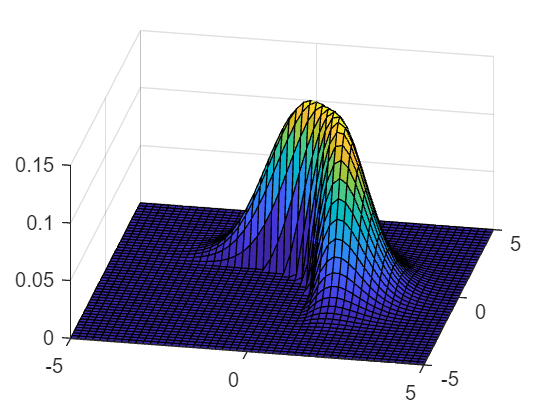

Z_K3 = reshape(targetfunction_K3(points), [n n]);
Z_K6 = reshape(targetfunction_K6(points), [n n]);

% 3D plot of the current example function
surf(x, y, Z_K3)
view([11.153 38.585])

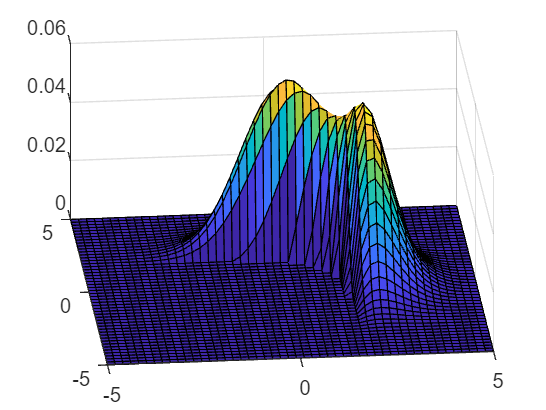

surf(x, y, Z_K6)
view([-5.4681 39.8152])

It seems like the optimal shift of the mean for importance sampling is a diagonal, meaning if we shift $X_1$ towards $+\infty$ we shift $X_2$ towards $-\infty$ in the same manner. Lets check some values of $(\mu_1^\ast,\mu_2^\ast)$

mu_1_K3 = 1.12245;
mu_2_K3 = 1.12245;

mu_1_K6 = 1.57;
mu_2_K6 = 1.57;

and perform importance sampling by hand (since there is some issue with input arguments for the "Monte_Carlo_HW1_Gaussian_Samples_shifed.m" function, "f_max_exp_K3.m" respectively).

% Number of samples for Importance sampling
M_IS = 100;

% Generate shifted normal samples
sample1_K3 = normrnd(mu_1_K3, 1, [1, M_IS]);
sample2_K3 = normrnd(mu_2_K3, 1, [1, M_IS]);
samples_K3 = [sample1_K3; sample2_K3];

sample1_K6 = normrnd(mu_1_K6, 1, [1, M_IS]);
sample2_K6 = normrnd(mu_2_K6, 1, [1, M_IS]);
samples_K6 = [sample1_K6; sample2_K6];

% Get the corresponding function value samples
y_values_K3 = shifted_targetfunction_K3(samples_K3, mu_1_K3, mu_2_K3);
y_values_K6 = shifted_targetfunction_K6(samples_K6, mu_1_K6, mu_2_K6);

% Compute the MC estimate
format long
MC_est_K3 = (1/M_IS)*sum(y_values_K3)

MC_est_K3 =    1.247492558236894


MC_est_K6 = (1/M_IS)*sum(y_values_K6)

MC_est_K6 =    0.554062627166612



% Compute, if nessesary, the sample variance of our MC estimate
MC_var_K3 = (1/(M_IS-1))*sum((y_values_K3 - MC_est_K3).^2)

MC_var_K3 =    1.524373153962604


MC_var_K6 = (1/(M_IS-1))*sum((y_values_K6 - MC_est_K6).^2)

MC_var_K6 =    2.481687075589581


Now we will use a reference solution which comes from a Monte Carlo Estimate using Importance Sampling with a shift dilation technique and $M=10^6$ samples.

K3_ref_sol = 1.091257082932551;
K6_ref_sol = 0.417492762191483;

Now we can plot the "exact error" and statistical error against the number of samples $M$ used.

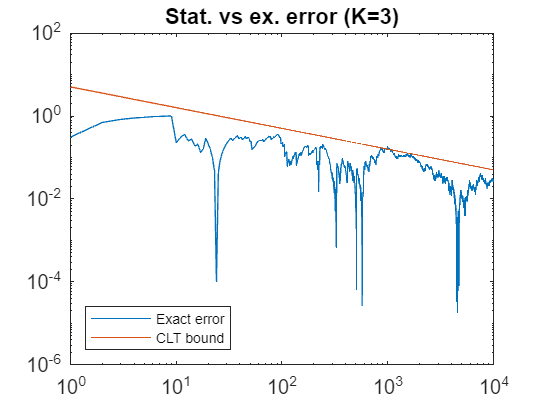

c_alpha = 1.96;
M = 10000;

estimates_K3 = zeros([1 M]);
variances_K3 = zeros([1 M]);
estimates_K6 = zeros([1 M]);
variances_K6 = zeros([1 M]);
exact_err_K3 = zeros([1 M]);
stat_err_K3 = zeros([1 M]);
exact_err_K6 = zeros([1 M]);
stat_err_K6 = zeros([1 M]);
for k=1:M
    rng(1)
    [estimates_K3(k), variances_K3(k)] = Monte_Carlo_HW1_Gaussian_Samples(@f_max_exp_K3, k);
    [estimates_K6(k), variances_K6(k)] = Monte_Carlo_HW1_Gaussian_Samples(@f_max_exp_K6, k);
    exact_err_K3(k) = abs(estimates_K3(k) - K3_ref_sol);
    exact_err_K6(k) = abs(estimates_K6(k) - K6_ref_sol);
end

for k=1:M
    stat_err_K3(k) = c_alpha*sqrt(variances_K3(end))/sqrt(k);
    stat_err_K6(k) = c_alpha*sqrt(variances_K6(end))/sqrt(k);
end

%plot(1:M, estimates_K3, 1:M, K3_ref_sol)
%title("MC est. & ref. sol. K=3")
loglog(1:M, exact_err_K3, 1:M, stat_err_K3)
legend('Exact error', 'CLT bound', fontsize=7, location='southwest')
title("Stat. vs ex. error (K=3)")

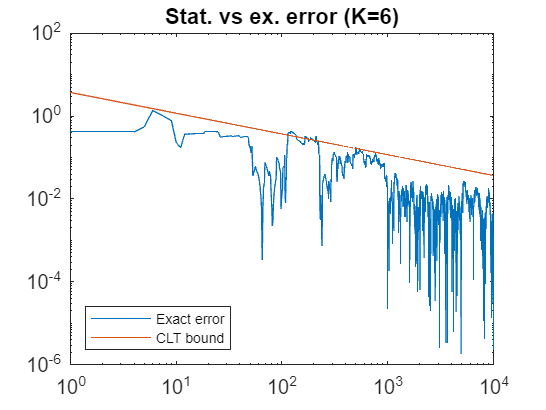

%plot(1:M, estimates_K6, 1:M, K6_ref_sol)
%title("MC est. & ref. sol. K=6")
loglog(1:M, exact_err_K6, 1:M, stat_err_K6)
legend('Exact error', 'CLT bound', fontsize=7, location='southwest')
title("Stat. vs ex. error (K=6)")

Now we will do the same computations using Importance sampling

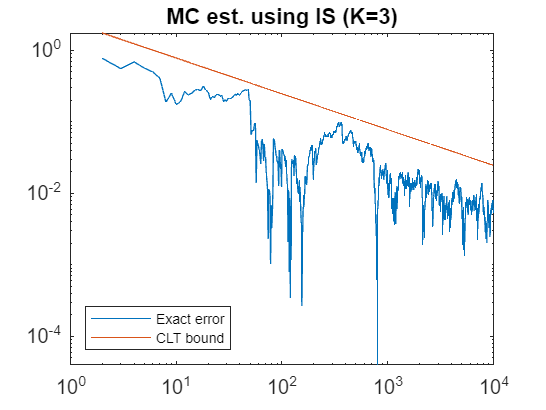

M_ = 10000;
MC_est_K3 = zeros([1 M_]);
stat_err_IS_K3 = zeros([1 M_]);
exact_err_IS_K3 = zeros([1 M_]);
MC_est_K6 = zeros([1 M_]);
stat_err_IS_K6 = zeros([1 M_]);
exact_err_IS_K6 = zeros([1 M_]);

sample1_K3 = normrnd(mu_1_K3, 1, [1, M_]);
sample2_K3 = normrnd(mu_2_K3, 1, [1, M_]);
samples_K3 = [sample1_K3; sample2_K3];

sample1_K6 = normrnd(mu_1_K6, 1, [1, M_]);
sample2_K6 = normrnd(mu_2_K6, 1, [1, M_]);
samples_K6 = [sample1_K6; sample2_K6];

y_values_K3 = shifted_targetfunction_K3(samples_K3, mu_1_K3, mu_2_K3);
y_values_K6 = shifted_targetfunction_K6(samples_K6, mu_1_K6, mu_2_K6);

for k=2:M_
    MC_est_K3(k) = (1/k)*sum(y_values_K3(:,1:k));
    MC_est_K6(k) = (1/k)*sum(y_values_K6(:,1:k));
    MC_var_K3(k) = (1/(k-1))*sum((y_values_K3(:,1:k) - MC_est_K3(k)).^2);
    MC_var_K6(k) = (1/(k-1))*sum((y_values_K6(1,1:k) - MC_est_K6(k)).^2);
    exact_err_IS_K3(k) = abs(MC_est_K3(k) - K3_ref_sol);
    exact_err_IS_K6(k) = abs(MC_est_K6(k) - K6_ref_sol);
end

for k=2:M_
    stat_err_IS_K3(k) = c_alpha*sqrt(MC_var_K3(end))/sqrt(k);
    stat_err_IS_K6(k) = c_alpha*sqrt(MC_var_K6(end))/sqrt(k);
end

%plot(1:M_, MC_est_K3)
%title("MC est. using IS (K=3)")
%plot(1:M_, MC_est_K6)
%title("MC est. using IS (K=6)")

loglog(1:M_, exact_err_IS_K3, 1:M_, stat_err_IS_K3)
legend('Exact error', 'CLT bound', fontsize=7, location='southwest')
title("MC est. using IS (K=3)")

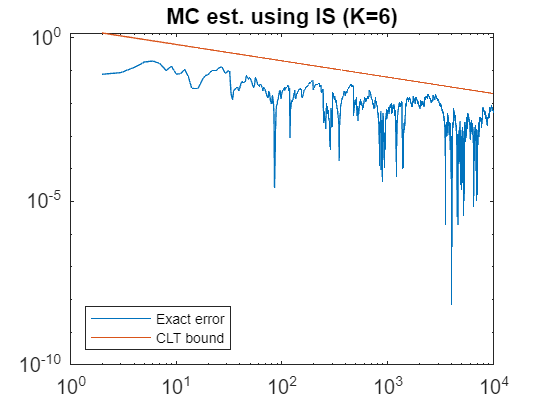


loglog(1:M_, exact_err_IS_K6, 1:M_, stat_err_IS_K6)
legend('Exact error', 'CLT bound', fontsize=7, location='southwest')
title("MC est. using IS (K=6)")